# Reinforcement learning for financial trading Demo

## Building constant variables

Test and train data building

% Data Set - Simulating 3 stocks, $20,000, 15 years of Closing Prices
% Training Data ~ 12 years
% Test Data ~ 3 years

% Choose to simulate data or fetch real financial data
[trainData,testData] = simulateStockData;
% [trainData,testData] = fetchStockData;

## Action vectors creation

% Action Combinations for Stock
% 0 - sell, 1 - hold, 2 - buy
% This results in 27 Action combinations. E.g.:
% Action_Vectors = [0 0 0;0 0 1;...;1 1 0;1 1 1 ];
x = 0:1:2;
y = 0:1:2;
z = 0:1:2;
[X,Y,Z] = meshgrid(x,y,z);
for i = 1:numel(X)
    Action_Vectors(i,:) = [Z(i),X(i),Y(i)];
end

## Reset and step function creation

ResetHandle = @() myResetFunction(trainData);
StepHandle = @(Action,StockSaved) myStepFunction(Action,StockSaved,trainData,Action_Vectors,true);
ResetHandleT = @() myResetFunction(testData);
StepHandleT = @(Action,StockSaved) myStepFunction(Action,StockSaved,testData,Action_Vectors,false);

## Observation definition

% Input size of Actor / Critic is 19, which maps to the state vector. 
% For 3 stocks this state vector equals-
% 3 x Stocks Owned
% 3 x Price Different when Bought
% 1 x Cash In Hand
% 3 x Price change from yesterday
% 3 x Price change from 2 days ago
% 3 x Price change from 7 days ago
% 3 x Price change from average price of 7 days ago

ObservationInfo = rlNumericSpec([1 19]);
ObservationInfo.Name = 'StockTrading States';
%the description is a single string to describe the states
ObservationInfo.Description = ['stockholdings, ', ...
    'stock buy price difference, ', ' cash, ', 'StockInd1, ' , 'StockInd2, ', 'StockInd3 '];

## Action definition

ActionInfo = rlFiniteSetSpec(1:27);
ActionInfo.Name = 'Stock Actions';

## Environment creation

env = rlFunctionEnv(ObservationInfo,ActionInfo,StepHandle,ResetHandle);

Step: 2/2598 Action: 9 Profit: 242.1291 Reward: 1 Reward action: 0


envT = rlFunctionEnv(ObservationInfo,ActionInfo,StepHandleT,ResetHandleT);

Step: 2/1114 Action: 19 Profit: -1045.1922 Reward: -1 Reward action: 0


## Creation of the AC Agent

Neural networks

criticNet = [
    imageInputLayer([1 19 1],"Name","state","Normalization","none")
    fullyConnectedLayer(128,"Name","Fully_128_1")
    tanhLayer("Name","tanh_activation1")
    fullyConnectedLayer(128,"Name","Fully_128_2")
    tanhLayer("Name","tanh_activation2")
    fullyConnectedLayer(64,"Name","Fully_64")
    reluLayer("Name","relu_activation1")
    fullyConnectedLayer(1,"Name","output")];

actorNet = [
    imageInputLayer([1 19 1],"Name","state","Normalization","none")
    fullyConnectedLayer(128,"Name","Fully_128_1")
    tanhLayer("Name","tanh_activation1")
    fullyConnectedLayer(128,"Name","Fully_128_2")
    tanhLayer("Name","tanh_activation2")
    fullyConnectedLayer(64,"Name","Fully_64")
    reluLayer("Name","relu_activation1")
    fullyConnectedLayer(27,"Name","action")];

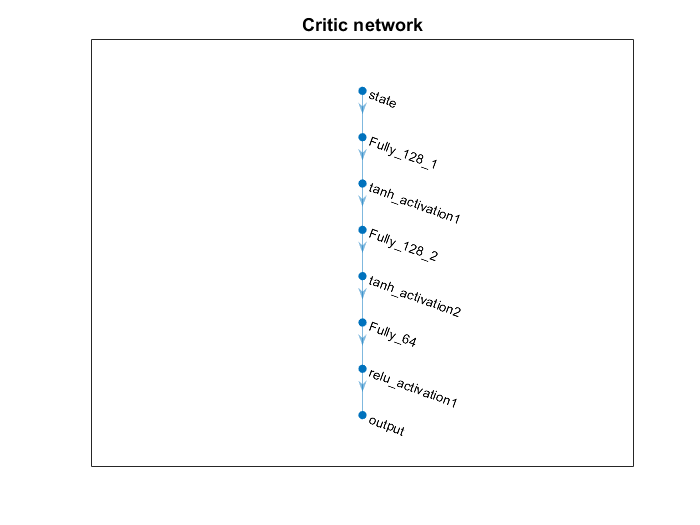

lgraph1 = layerGraph(criticNet);
lgraph2 = layerGraph(actorNet);

figure;
plot(lgraph1);
title('Critic network')

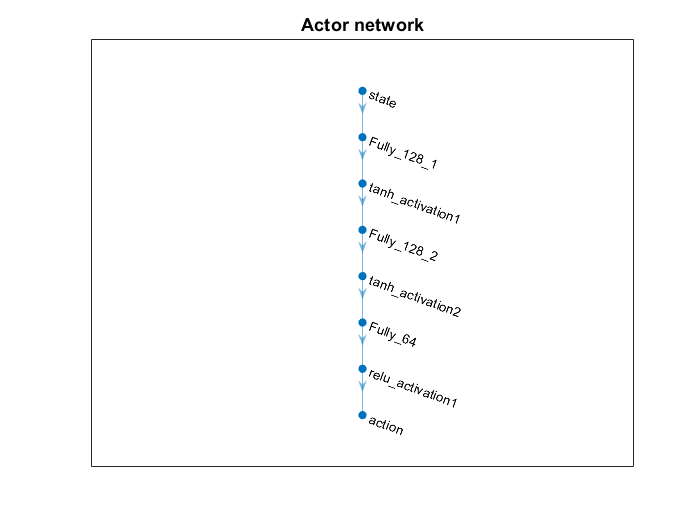

figure;
plot(lgraph2);
title('Actor network')

% Agent creation

obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);

criticOpts = rlRepresentationOptions('LearnRate',1e-3,'GradientThreshold',1,'UseDevice','cpu');
% 19b code 
% critic = rlRepresentation(criticNet,criticOpts,'Observation',{'state'},obsInfo);
% 20a code
critic = rlValueRepresentation(criticNet,obsInfo,'Observation',{'state'},criticOpts);

actorOpts = rlRepresentationOptions('LearnRate',1e-3,'GradientThreshold',1,'UseDevice','cpu');
% 19b code
% actor = rlRepresentation(actorNet,actorOpts,'Observation',{'state'},obsInfo,'Action',{'action'},actInfo);
% 20a code
actor = rlStochasticActorRepresentation(actorNet,obsInfo,actInfo,'Observation',{'state'},actorOpts);

agentOpts = rlACAgentOptions(...
    'NumStepsToLookAhead',64, ...

    'EntropyLossWeight',0.3, ...
    'DiscountFactor',0.9);
agent = rlACAgent(actor,critic,agentOpts);

## Agent Training

Training options

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', 5000, ...
    'MaxStepsPerEpisode', 4000, ...
    'Verbose', true, ...
    'Plots','training-progress',...
    'ScoreAveragingWindowLength',10,...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',100000000,...
    'SaveAgentCriteria',"EpisodeReward" ,...
    'SaveAgentValue', 30000,...
    'SaveAgentDirectory', pwd + "\agents\");
% Agent training

doTraining = false;
if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load('agent_3Stock_Jun03.mat','agent')       
end

## Simulation on Test data

Step: 2/1114 Action: 14 Profit: 526.5275 Reward: -1 Reward action: 0
Step: 3/1114 Action: 14 Profit: 550.3499 Reward: 1 Reward action: 0
Step: 4/1114 Action: 5 Profit: 1188.7763 Reward: 1 Reward action: 0
Step: 5/1114 Action: 14 Profit: 1257.1922 Reward: 1 Reward action: 0
Step: 6/1114 Action: 13 Profit: 1059.7748 Reward: -1 Reward action: 0
Step: 7/1114 Action: 18 Profit: 869.6402 Reward: -1 Reward action: 0
Step: 8/1114 Action: 24 Profit: 1025.0893 Reward: 1 Reward action: 0
Step: 9/1114 Action: 14 Profit: 1999.6758 Reward: 1 Reward action: 0
Step: 10/1114 Action: 14 Profit: 2685.6967 Reward: 1 Reward action: 0
Step: 11/1114 Action: 13 Profit: 2551.1724 Reward: -1 Reward action: 93.6974
Step: 12/1114 Action: 9 Profit: 2536.6329 Reward: 1 Reward action: 18.0092
Step: 13/1114 Action: 14 Profit: 2327.2163 Reward: -1 Reward action: 0
Step: 14/1114 Action: 5 Profit: 1771.1007 Reward: -1 Reward action: 6.529
Step: 15/1114 Action: 13 Profit: 2018.7867 Reward: 1 Reward action: 97.7634
Step: 

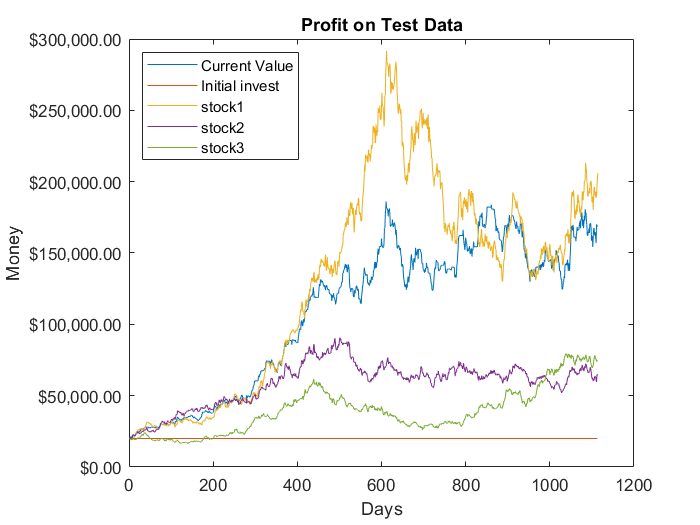

Step: 1114/1114 Action: 24 Profit: 148608.4845 Reward: -1 Reward action: 0


simOpts = rlSimulationOptions('MaxSteps',4000);
experience = sim(envT,agent,simOpts);

*Copyright 2020 The MathWorks, Inc.*